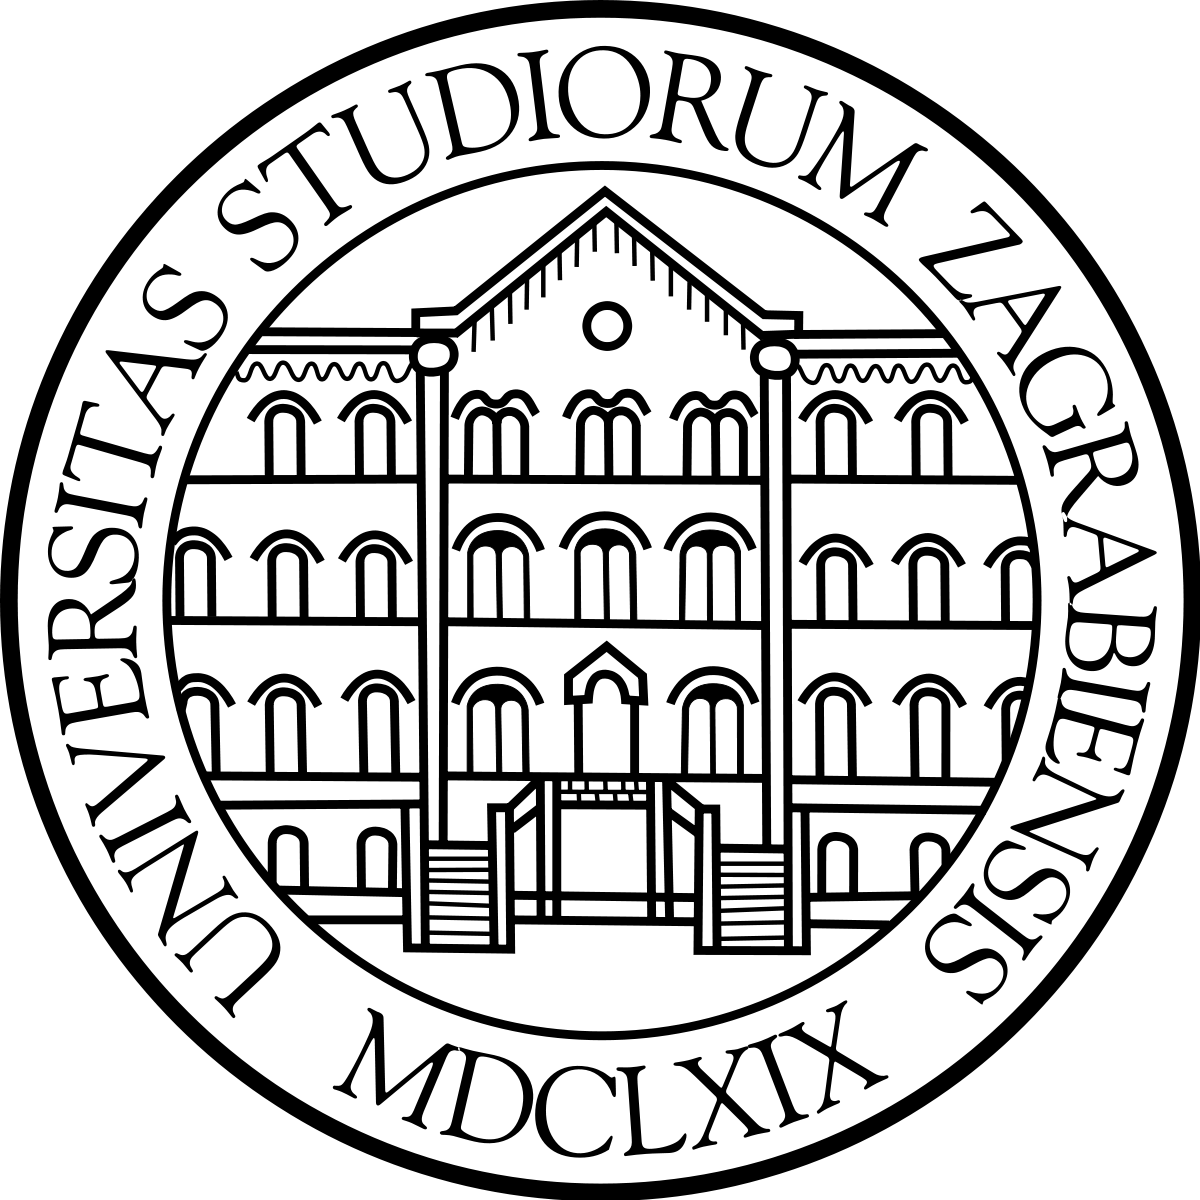

Sveučilište u Zagrebu

Fakultet elektrotehnike i računarstva

Zavod za elektroničke sustave i obradbu informacija

# Kratke upute za korištenje MATLAB-a na Signalima i sustavima

Tin Vlašić

Zagreb, 2023.

## 1. O MATLAB-u

MATLAB je programski jezik visoke razine koristan za rješavanje različitih matematičkih problema i vizualizaciju te posebno za dizajn i simulaciju sustava za obradu signala, upravljanje i identifikaciju. Naziv MATLAB je nastao kao kratica engleskih riječi *MATrix LABoratory*. Prva verzija MATLAB-a je napisana krajem 1970. godine na sveučilištima University of Mexico i Stanford University radi primjene u numeričkoj analizi i linearnoj algebri.

Danas je MATLAB puno više od *matričnog laboratorija*. Koriste ga inženjeri i znanstvenici u raznim područjima. Osim osnovnog sustava postoje i brojni paketi koji ga proširuju te pokrivaju djelatnosti poput: obrade signala i slike, 3D grafičkog prikaza, automatskog upravljanja, statističke obrade, strojnog učenja, dubokog učenja, financija i brojnih drugih. Jedan od važnijih paketa, kojeg ćete koristiti u sklopu laboratorijskih vježbi iz Signala i sustava, je *Simulink* -- alat za simulaciju kontinuiranih i diskretnih sustava pomoću funkcijskih blok dijagrama.

## 2. MATLAB sučelje

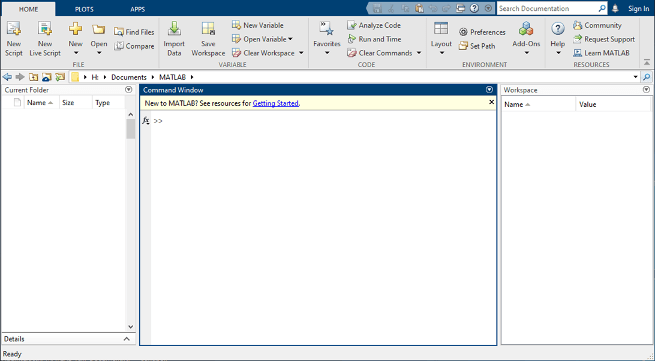

Kod pokretanja MATLAB-a otvorit će se sučelje slično kao na slici.

- **Current Folder (trenutni direktorij) **- pokazuje direktorij u kojem se trenutno nalazite i datoteke koje u njemu.

- **Command Window (naredbeni prozor) **- služi za unos naredbi. Naredbena linija je označena s (>>).

- **Workspace** **(radni prostor)** - sadrži sve prethodno kreirane varijable.

U naredbenom prozoru možete kreirati varijable i pozivati funkcije. Na primjer, da bi kreirali varijablu `a` vrijednosti `1` upišite ovu naredbu u naredbenu liniju:

a = 1

a = 1

Naredba se izvršava tipkom *Enter. *MATLAB će dodati varijablu `a` u radnom prostoru i prikazati rezultat u naredbenom prozoru.

Stavimo li točku sa zarezom (`;`) na kraj naredbe time označavamo da ne želimo ispis rezultata u naredbenom prozoru. Bez obzira na (`;`) obje varijante definiraju nove varijable u radnom prostoru.

Imena varijabli moraju počinjati slovom, a smiju sadržavati najviše$19$ alfanumeričkih znakova uključivši i donju crticu (_).

Kreirajmo još nekoliko varijabli.

b = 3

b = 3

c = a + b

c = 4

d = c * a + b + 1

d = 8

d_1 = d / c  % dijeljenje 

d_1 = 2

d_1^3  % potenciranje

ans = 8

Kada ne specificiramo izlaznu varijablu kao u posljednjem slučaju, MATLAB koristi varijablu `ans` (kratica za *answer*) i tamo sprema posljednji rezultat.

d2 = 2e-3  % 0.002

d2 = 0.0020

Eksponencijalni zapis 2`e-3` jednak je $2\times {10}^{-3}$ i iznosi $0\ldotp 002\ldotp$

Popis svih varijabli koje trenutno postoje u radnom prostoru vidljiv je korištenjem naredbe `whos`:

whos

  Name      Size            Bytes  Class     Attributes

  a         1x1                 8  double              
  ans       1x1                 8  double              
  b         1x1                 8  double              
  c         1x1                 8  double              
  d         1x1                 8  double              
  d2        1x1                 8  double              
  d_1       1x1                 8  double              



Ispis sadržaja varijable u radnom prostoru postiže se unosom njenog imena (bez `;`):

a

a = 1

Brisanje varijabli iz radnog prostora izvršava se naredbom `clear`:

clear a   % briše varijablu a
clearvars % briše sve varijable

Brisanje prijašnjih naredbi zapisanih u naredbenom prozoru izvršava se naredbom `clc:`

clc 

## 3. MATLAB live skripta

MATLAB live skripta je interaktivni dokument koji kombinira MATLAB kod s tekstom, jednadžbama i slikama u jednom okruženju -- Live Editoru. Live skripte spremaju i prikazuju izlaze iz kodova koji ih kreiraju. Live skripta dozvoljava pokretanje blokova kodova individualno ili pokretanje cijelog dokumenta odjenom te prikazuje rezultate i grafičke prikaze s kodom koji ih je producirao. Ekstenzija dokumenta je `mlx`. Kako bi pokrenuli MATLAB live skriptu pozicionirajte se u direktorij u kojem se nalazi live skripta ili live skriptu kopirajte u trenutni direktorij (*Current Folder*). Pozicionirati se možete pomoću naredbe `cd` (*change directory*), npr. >> `cd 'C:\Users\user_name\Signali_i_sustavi\lab1'`.

Ova MATLAB live skripta služi kao interaktivni dokument za upoznavanje s MATLAB-om. Osim popratnog teksta dan je i MATLAB kod. Sekcije unutar MATLAB live skripte možete pokretati pomoću opcije *Run current section *(Ctrl + Enter) ili *Run current section and advance to next section *(Ctrl + Shift + Enter) i izborniku LIVE EDITOR. Kodove možete mijenjati i pokretati ih više puta. Na kraju pojedinih sekcija zadani su dodatni zadaci koje je poželjno riješiti kako bi sami provjerili jeste li usvojili najvažnije naredbe i logiku iz te i prethodnih sekcija. Rješenja zadataka ne šaljete nastavnicima niti ih predajete.

## 4. Nizovi i matrice

MATLAB je dizajniran za operacije primarno nad cijelim nizovima i matricama. Sve varijable u MATLAB-u su višedimenzionalni nizovi, neovisno o tipu podataka. *Matrica *je definirana kao dvodimenzionalni niz.

### 4.1. Kreiranje niza

Za kreiranje niza s$$N$$elemenata u jednom retku, razdvojite elemente zarezom (`,`) ili razmakom (*space*):

a = [1, 2, 3, 4]

a =      1     2     3     4


b = [1 2 3 4]

b =      1     2     3     4


Ovaj tip niza je red-vektor.

Kako bi kreirali stupac-vektor, razdvojite elemente točka sa zarezom (`;`):

c = [1; 5; 10; 15]

c =      1
     5
    10
    15


Pristup pojedinim elementima niza moguć je korištenjem okruglih zagrada:

a(1)  % pristupanje prvom elementu

ans = 1

b(4)  % pristupanje četvrtom (ujedno i zadnjem elementu)

ans = 4

b(end)  % pristupanje zadnjem elementu

ans = 4

Zadnjem elementu u nizu moguće je pristupiti i pomoću operatora `end`.

Kako bi pristupili više elemenata unutar niza mogće je koristit indeksiranje:

c([1,3])  % pristupanje prvom i trećem elementu

ans =      1
    10


Pristup više uzastopnim elementima moguć je pomoću:

c(1:3)  % pristupanje od prvog do trećeg elementa

ans =      1
     5
    10


c(2:end)  % pristupanje od drugog do zadnjeg elementa

ans =      5
    10
    15


Napomenimo kako indeksiranje u MATLAB-u počinje od indeksa `1`.

#### 4.1.1. Posebne naredbe za kreiranje nizova

Nizovi brojeva se mogu kreirati pomoću naredbe `linspace:`

d = linspace(1, 10, 10)

d =      1     2     3     4     5     6     7     8     9    10


Naredba `linspace(x1, x2, n) generira n `jednako razmaknutih točaka između `x1` i `x2`.

Alternativna naredba je operator ```:`˝ koji se koristi na sljedeći način:

e = 1:1.5:10

e =     1.0000    2.5000    4.0000    5.5000    7.0000    8.5000   10.0000


Naredba (`x1:step:x2`) generira točke počevši od `x1` s korakom `step` između točaka sve do točke `x2.` Razlika između operatora ```:`˝ i naredbe `linspace` je što `linspace` daje direktnu kontrolu nad brojem generiranih točaka i uvijek uključuje zadnju točku `x2`, dok operator ```:`˝ daje kontrolu nad korakom, odnosno razmakom između dvije susjedne točke.

**Zadatak 1. **Generirajte niz x od $20$ jednako razmaknutih točaka kojem je prvi element jednak $0$, a zadnji $1\ldotp$ Izdvojite iz niza `x` prvi element i zadnjih $10$ elemenata (elemente od $11\ldotp$ do zadnjeg indeksa) te ih spremite u novi niz y.

**Zadatak 2. **Generirajte niz x kojem je prvi element jednak $10$, a neka mu zadnji element bude jednak $9$. Razlika između susjedna dva elementa neka bude $-0\ldotp 1$. Koliko elemenata ima niz x? Izdvojite iz niza prvi, drugi, peti i sedmi element te ih spremite u novi niz `z`. 

### 4.2. Kreiranje matrica

Za kreiranje matrice, razdvojite redove točka sa zarezom (;):

A = [1 2 3; 3 2 4; 2 2 3]

A =      1     2     3
     3     2     4
     2     2     3


B = [1, 3; 2, 1; 2, 2]

B =      1     3
     2     1
     2     2


Napomenimo da MATLAB razlikuje velika i mala slova pa su varijable `A` i `a`, `B` i `b` različite i vidljive u radnom prostoru.

Slično kao i kod nizova, pristup pojedinim elementima matrica moguć je korištenjem okruglih zagrada:

A(1, 1)  % ispis elementa matrice A u prvom retku i prvom stupcu

ans = 1

B(2, end)  % ispis elementa matrice B u drugom retku i zadnjem stupcu

ans = 1

A(1:2, 1:2)  % ispis 2x2 podmatrice matrice A

ans =      1     2
     3     2


Operator dvotočka bez zadanog raspona daje sve elemente nekog stupca ili retka:

A(:, 2)  % ispis drugog stupca matrice A

ans =      2
     2
     2


C = A(1:2, :)  % spremanje prvog i drugog reda matrice A u novu matricu C

C =      1     2     3
     3     2     4


#### 4.2.1. Posebne naredbe za kreiranje matrica

Matrice se mogu kreirati i na način da se pozove funkcija, kao što je `zeros`, `eye`, `ones`, `randi` ili `rand`. Na primjer, $3\times 3$ jedinična matrica definira se kao:

eye(3)

ans =      1     0     0
     0     1     0
     0     0     1


Matrica ispunjena nulama kreira se pomoću naredbe `zeros`, a jedinicama pomoću naredbe `ones`. Na primjer, $5\times 2$ matrice ispunjena nulama:

zeros(5, 2)

ans =      0     0
     0     0
     0     0
     0     0
     0     0


Matrica ispunjena slučajnim vrijednostima može se kreirati pomoću naredbi `rand` ili `randi`. Na primjer, $4\times 3$ matrica s cjelobrojnim elementima:

randi([1, 10], 4, 3)  % bira nasumično vrijednosti elemenata iz skupa {1, 2, ..., 10}

ans =      8     5     8
    10     1     4
     2     4     6
     6     2     2


E = rand(4,3)  % vrijednosti su uzorci iz normalne distribucije na intervalu [0, 1]

E =     0.6020    0.7482    0.9133
    0.2630    0.4505    0.1524
    0.6541    0.0838    0.8258
    0.6892    0.2290    0.5383


Slično se mogu definirati i red-vektori odnosno stupac-vektori. Na primjer, red-vektor s $10$ elemenata vrijednosti nula:

f = zeros(1, 10)

f =      0     0     0     0     0     0     0     0     0     0


**Zadatak 3. **Generirajete slučajnu $5\times 5$ matricu `B` pomoću naredbe `randi` koja može poprimiti cjelobrojne vrijednosti od $-3$ do $3$. Izdvojite $2\times 2$ podmatricu matrice `B` čiji se prvi `(1, 1)` element nalazi na nasumično odabranom indeksu (`idx_row, idx_col`) matrice `B` (mogući nasumični indeksi za `idx_row` i `idx_col` su od $1$ do $4$). Koristite `randi` za generiranje nasumičnih indeksa.

### 4.3. Kompleksni brojevi

Kompleksni brojevi imaju realni i imaginarni dio. Imaginarna jedinica je kvadratni korijen od `-1`:

sqrt(-1)

ans = 0.0000 + 1.0000i

Za reprezentaciju imaginarnog dijela kompleksnog broja koristi se `i` ili `j`:

c = [1-2j, 1i, -1-1j]

c =    1.0000 - 2.0000i   0.0000 + 1.0000i  -1.0000 - 1.0000i


Napomenimo kako je u MATLAB-u moguće promijeniti vrijednost svih varijabli, pa tako i posebnih. Stoga se preporučuje koristiti definicijski izraz `sqrt(-1)` ili broj uz imaginarnu jedinicu (npr. `1i` ili `1j`), pogotovo u vlastitim skriptama i funkcijama jer se `i` ili `j` obično iskoriste kao brojači u `for` petlji. Postoje i druge posebne varijable kao što su `pi` ($\pi$), `inf` za beskonačnu vrijednost ili `NaN` (*not a number*).

Za pristup realnom, odnosno imaginarnom dijelu kompleksnih brojeva koriste se funkcije `real()` i `imag()`, dok funkcije `abs()` i `angle()` daju komponente polarnog modela kompleksnog broja: apsolutnu vrijednost ili modul, te fazu u radijanima.

real(c)

ans =      1     0    -1


imag(c)

ans =     -2     1    -1


abs(c)

ans =     2.2361    1.0000    1.4142


angle(c)

ans =    -1.1071    1.5708   -2.3562


### 4.4. Matematičke operacije nad nizovima i matricama

MATLAB dozvoljava operacije nad svim elementima u nizu ili matrici koristeći jedan aritmetički operator ili funkciju.

a = [1, 3, 4.5, 2];
a / 2  % dijeljenje s 2

ans =     0.5000    1.5000    2.2500    1.0000


a - 1  % oduzimanje s 1

ans =          0    2.0000    3.5000    1.0000


A = [1 2 3; 3 2 4; 2 2 3];
A + 10  % zbrajanje s 10

ans =     11    12    13
    13    12    14
    12    12    13


A * 2  % množenje s 2

ans =      2     4     6
     6     4     8
     4     4     6


U MATLAB-u je adjungirani operator jednak (`'`):

b = [1-1j, 2-3j];
b'

ans =    1.0000 + 1.0000i
   2.0000 + 3.0000i


D = randi([1, 10], 4, 3)

D =     10    10     9
     1     1     1
     5     8     4
     2     9     3


D'

ans =     10     1     5     2
    10     1     8     9
     9     1     4     3


Inverz matrice računamo pomoću naredbe `inv`:

B = inv(A)

B =    -1.0000   -0.0000    1.0000
   -0.5000   -1.5000    2.5000
    1.0000    1.0000   -2.0000


Matrično množenje definirano je pomoću operatora (`*`):

D * A

ans =     58    58    97
     6     6    10
    37    34    59
    35    28    51


MATLAB dozvoljava i operacije po elementima. Tada prije željenog operatora stavljamo točku `.` (npr. `.*`, `.^`, `./`). Na primjer, množenje i potenciranje po elementima dviju matrica:

A .* B

ans =    -1.0000   -0.0000    3.0000
   -1.5000   -3.0000   10.0000
    2.0000    2.0000   -6.0000


A .^ B

ans =     1.0000    1.0000    3.0000
    0.5774    0.3536   32.0000
    2.0000    2.0000    0.1111


Za transponiranje vektora ili matrice koristi se operator (`.'`)`:`

b.'

ans =    1.0000 - 1.0000i
   2.0000 - 3.0000i


**Zadatak 4. **Za matricu `F=[2, 1; 3, 2]` izračunajte inverz i njenu transponiranu matricu. Izdvojite iz transponirane matrice zadnji stupac te po elementima pomnožite inverznu matricu i izdvojeni stupac.

### 4.5. Relacijski operatori

MATLAB podržava sljedeće relacijske operatore:

a = [1, 2, 3];
b = [2, 1, 2];
a < b  % manje

ans = 1×3 logical array
   1   0   0


a <= 2  % manje ili jednako

ans = 1×3 logical array
   1   1   0


a > 2  % veće

ans = 1×3 logical array
   0   0   1


a >= b  % veće ili jednako

ans = 1×3 logical array
   0   1   1


a ~= b  % različito

ans = 1×3 logical array
   1   1   1


c = a == b  % jednako

c = 1×3 logical array
   0   0   0


Rezultat relacijskog operatora je `1` ako je uvjet zadovoljen ili `0` ako uvjet nije zadovoljen.

**Zadatak 5. **Generirajte dvije $3\times 3$ matrice `C` i `D`. Pomoću relacijskih operatora provjerite koji su im elementi jednaki, a koji različiti. Provjerite koji elementi u matrici `C` su veći od elemenata matrice `D` za iste indekse. Provjerite postoje li elementi negativnih vrijednosti u matrici `C`? Provjerite postoje li i koji su elementi u matrici `D` vrijednosti $0$.

### 4.6. Operacije nad nizovima i matricama

Osim osnovnih matematičkih operacija na nizove je moguće primjenjivati i različite funkcije, npr.:

a = 1:2:7

a =      1     3     5     7


mean(a)

ans = 4

cos(a)

ans =     0.5403   -0.9900    0.2837    0.7539


Za svaki operator ili funkciju, kao i za čitave programske pakete u MATLAB-u postoje detaljne upute. Unutar MATLAB naredbenog prozora do njih se dolazi korištenjem naredbe `help`.

help cos

 cos    Cosine of argument in radians.
    cos(X) is the cosine of the elements of X. 
 
    See also acos, cosd, cospi.

    Documentation for cos
    Other functions named cos



Slično, osim osnovnih matematičkih operacija na matrice je moguće primjenjivati i različite funkcije. Neke od njih operiraju nad pojedinim elementima matrice, neke nad stupcima, a neke nad cijelim matricama. 

Elementarne funkcije primjenjuju se na svaki element matrice, npr.:

A = randi([-5, 5], 3)

A =      3    -3    -4
    -1    -3     4
     5    -4     1


cos(A)  % kosinus svakog elementa matrice A

ans =    -0.9900   -0.9900   -0.6536
    0.5403   -0.9900   -0.6536
    0.2837   -0.6536    0.5403


sin(A)  % sinus svakog elementa matrice A

ans =     0.1411   -0.1411    0.7568
   -0.8415   -0.1411   -0.7568
   -0.9589    0.7568    0.8415


Neke od preostalih funkcije operiraju nad stupcima matrice. Stupci matrice se tada tretiraju kao neovisni vektori na koje se primjenjuje zadana operacija. Npr. `max(A)` daje vrijednosti najvećih elemenata svakog stupca od `A`, `min(A)` daje vrijednosti najmanjih elemenata svakog stupca od `A`, `sum(A)` daje zbroj svih elemenata stupaca, itd.

max(A)

ans =      5    -3     4


sum(A)

ans =      7   -10     1


Maksimalni element u višedimenzionalnom nizu moguće je naći uzastopnim korištenjem naredbe `max`:

max(max(A))

ans = 5

 a srednju vrijednost svih elemenata u matrici korištenjem naredbe `mean`:

mean(mean(A))

ans = -0.2222

**Zadatak 6. **Generirajte niz `t` s $2000$ elemenata kojem je prvi element jednak $0$, a zadnji $2\pi$. Primjenite `cos` operator nad nizom i spremite vrijednosti u novi niz `x`. Svim elementima u nizu `x` dodajte vrijednost $0\ldotp 25$. Odredite maksimalnu i minimalnu vrijednost u nizu `x`. Odredite srednju vrijednost svih elemenata u nizu `x`.

## 5. Prikaz rezultata

Da bi mogli grafički prikazati rezultate moramo otvoriti novi prozor za njihov prikaz što se postiže naredbom `figure`. Možemo imati više različitih grafičkih prozora. MATLAB-ove naredbe za crtanje kao što je plot crtaju u trenutno aktivni prozor. Želimo li crtati u neki određeni prozor prije crtanja ga je potrebno odabrati, odnosno učiniti aktivnim. Stoga svaki grafički prozor ima svoj broj koji ga identificira te koji se koristi prilikom odabira aktivnog prozora pomoću naredbe `figure`.

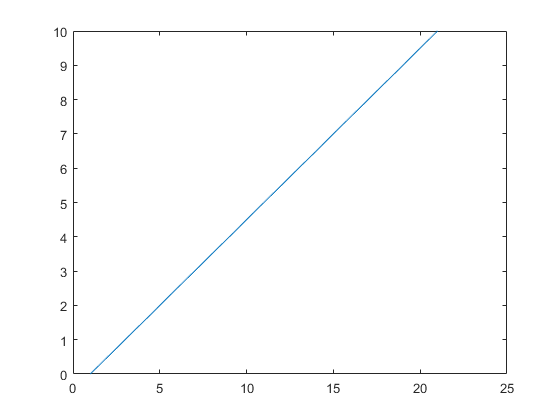

t = 0:0.5:10;
figure(1);  % čini prozor s brojem 1 aktivnim ili otvara novi prozor
            % ako takav ne postoji
plot(t);  % crtamo vektor t u prozor 1

Naredba `plot(t)` crta vektor `t` na taj način da se na x-osi nalaze indeksi niza `t`, a na y-osi nalaze vrijednosti niza. Ako koristimo naredbu `plot` ili bilo koju naredbu za crtanje te ako ne postoji aktivni grafički prozor MATLAB će otvoriti jedan. Na samom prikazu naredba `plot` zadane točke oblika (indeks, vrijednost vektora za indeks) spaja pravcima. Ako ne želimo spajati točke pravcima možemo koristiti sljedeće: 

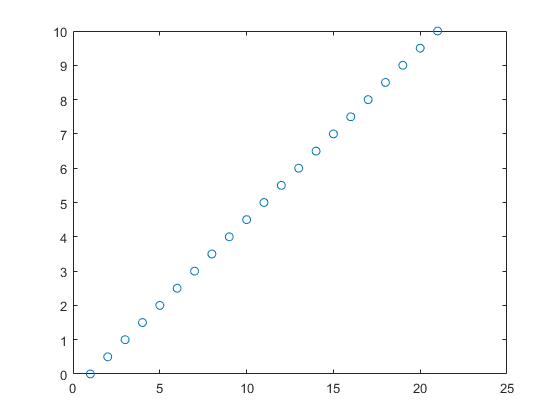

plot(t, 'o');  % crta pojedine točke pomoću kružića ali ih ne spaja

% sljedeće naredbe isprobajte sami (odkomentirajte sljedeće naredbe)
% stem(t);  % stupčasti prikaz diskretnih signala
% stairs(t);  % stepeničasti prikaz (po dijelovima konstantan)

Osim prikaza jednog vektora u zavisnosti o indeksu možemo nacrtati i već prethodno zadane parove točaka `(t, y)`. Pri tome se funkciji `plot` prosljeđuju dva vektora od kojih prvi sadrži x-koordinate dok drugi sadrži y-koordinate. Pri tome oba vektora moraju imati jednak broj elemenata. Ovakav prikaz se i najčešće koristi. Za označavanje koordinatnih osi i dodavanje naslova na prikazu koriste se naredbe `xlabel()`, `ylabel()` te `title()`.

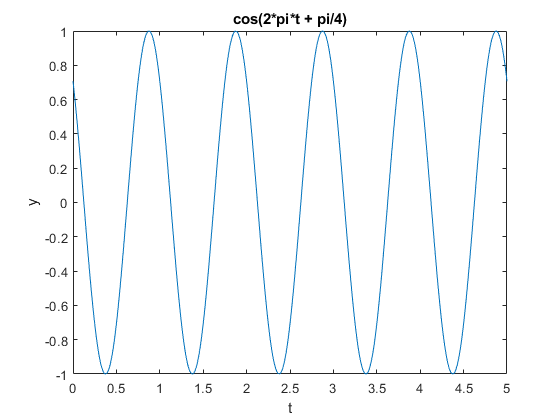

t = 0:0.01:5;
y = cos(2*pi*t + pi/4);
plot(t, y); 
xlabel('t');  % označava x-koordinatu
ylabel('y');  % označava y-koordinatu
title('cos(2*pi*t + pi/4)')  % dodaje naslov

Možemo istodobno nacrtati i više različitih parova signala. Općenito naredba `plot` očekuje ulazne podatke koji su redom x-koordinate, y-koordinate, način crtanja pa opet x-koordinate, y-koordinate, način crtanja itd. Pri tome neki od elemenata ponekad mogu biti izostavljeni. Naredba `legend` dodaje legendu s deskriptivnim oznakama za svaki par signala.

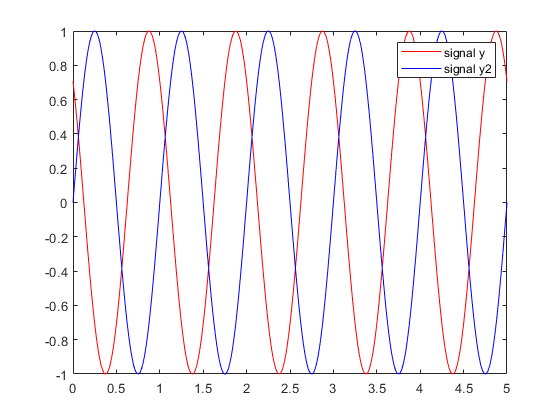

y2 = sin(2*pi*t);
plot(t, y, 'r', t, y2, 'b');  % 'r' označava crvenu boju, 'b' plavu
legend('signal y', 'signal y2')  % dodajemo legendu

Svaka naredba `plot` i općenito svako crtanje u grafički prozor briše prethodni sadržaj prozora. Ukoliko želimo crtati preko već nacrtanog moramo prije naredbe plot zadati naredbu `hold on`. Ova mogućnost se isključuje zadavanjem naredbe `hold off`.

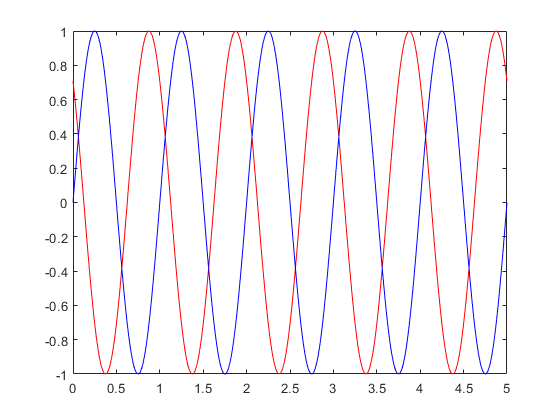

% crtanje u isti prozor pomoću hold on-a pozivajući dva puta naredbu plot
plot(t, y, 'r');
hold on;
plot(t, y2, 'b');
hold off;

Svaki prozor za crtanje se može zatvoriti naredbom `close`.

close all  % zatvaranje svih otvorenih prozora

Zanimljiva je i naredba `subplot`. Ona nam omogućuje crtanje više grafičkih prikaza u jednom prozoru.

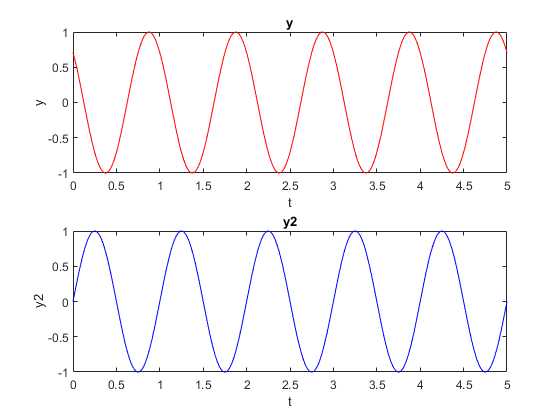

figure;
subplot(211); plot(t, y, 'r');  % prozor je podijeljen u 2 reda i 1 stupac (*21*1)
                                % crtamo u prvi odjeljak (21*1*)
title('y')
xlabel('t')
ylabel('y')
subplot(212); plot(t, y2, 'b');  % drugi signal crtamo u drugi odjeljak (21*2*)
title('y2')
xlabel('t')
ylabel('y2')

**Zadatak 7. **Nacrtajte parove točaka `(t, x)` iz zadatka 6. Označite koordinatne osi i dodajte proizvoljni naslov. Neka signal bude nacrtan crvenom bojom.

## 6. Simbolička matematika

Jedan od mnogih programskih paketa/modula unutar MATLAB-a podržava simboličku matematiku. Njegove mogućnosti možete pogledati naredbom help `symbolic`, dok naredba `symintro` daje kratki uvod s primjerima.

Simboličku varijablu definiramo na sljedeći način:

x = sym('x')  % definiramo simboličku varijablu

$$x = x$$

Svaki simbolički objekt može imati i dodatna svojstva koja se određuju kod deklaracije varijable:

y = sym('y', 'real')  % realna simbolička varijabla x

$$y = y$$

Ukoliko dodatna svojstva nisu bitna naredbom `syms` možemo odmah definirati više simboličkih varijabli

syms x y z  % definiramo tri simboličke varijable

MATLAB naredbe na simboličkim varijablama izvršavaju se simbolički:

x + 1 - y

$$ans = x-y+1$$

Korištenjem simboličkih izraza mogu se definirati i simboličke funkcije koje se potom mogu derivirati, integrirati itd.

syms a
fun = cos(a*x + y)

$$fun = \cos\left(y+a\,x\right)$$

diff(fun, x)  % derivacija funkcije po x

$$ans = -a\,\sin\left(y+a\,x\right)$$

int(fun, x)  % neodređeni integral funkcije po x

$$ans = \frac{\sin\left(y+a\,x\right)}{a}$$

syms t1 t2  % donja i gornja granica integrala
int_rez = int(fun, x, t1, t2)  % određeni integral funkcije po x

$$int\_rez = -\frac{\sin\left(y+a\,t_{1}\right)-\sin\left(y+a\,t_{2}\right)}{a}$$

Simboličke funkcije mogu se nacrtati korištenjem naredbe `fplot`.

fun = 2*x^2 + 5*x + 54  % definiramo kvadratnu funkciju

$$fun = 2\,x^{2}+5\,x+54$$

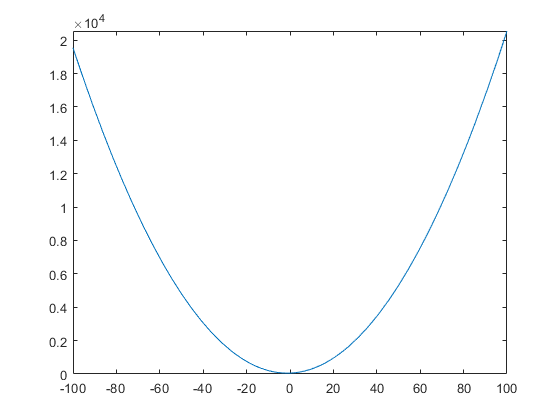

figure;
fplot(fun, [-100, 100])  % crtamo na intervalu [-100, 100]

Kako bi izračunali vrijednost funkcije u određenoj točci ili zamijenili jednu od simboličkih varijabli konstantom koristimo naredbu `subs`

subs(fun, x, 2)  % vrijednost funkcije f u točci x=2

$$ans = 72$$

subs(int_rez, [t1, t2, a], [0, 1, pi])

$$ans = -\frac{2\,\sin\left(y\right)}{\pi }$$

**Zadatak 8. **Korištenjem simboličkih izraza definirajte simboličke varijable `t, t1, t2`. Definirajte simbolički funkciju $y=\cos \left(2\pi \;t\right)\ldotp$Simbolički izračunajte određeni integral funkcije $y$ na intervalu $\left\lbrack t_1 ,t_2 \right\rbrack$. Ako s $T$ označimo period funkcije $y$, koristeći naredbu `subs` izračunajte rezultat integrala za granice $t_1 =0$ i $t_{2\;} =\frac{T}{2}$.

## 7. Programiranje u MATLAB-u

U MATLAB-u je moguće pisati vlastite programske odsječke. Naredbe je moguće izvršitit uvjetno ili ponavljati.

Svaki skup MATLAB naredbi napisan korištenjem bilo kojeg tekst editora koji je pohranjen u datoteci s nastavkom .m predstavlja jedan MATLAB program. Svi MATLAB programi se spremaju u obične tekstualne datoteke a najjednostavnije ih je pisati korištenjem ugrađenog editora koji se poziva naredbom `edit`.

### 7.1. MATLAB skripte

Editor možemo koristiti za pisanje MATLAB skripta. MATLAB skripta je niz naredba koje MATLAB izvodi slijedno. Kako bi pokrenuli MATLAB skriptu, prvo ju moramo spremiti. Spremanje skripte vrši se klikom na ikonu *Save* u izborniku (ili Ctrl + S).  Sve varijable deklarirane unutar MATLAB skripte postoje i vidljive su u radnom prostoru. Jedan primjer MATLAB skripte dan je uz ove materijale i naziva se *skripta.m*.

Obični komentar počinje znakom `%`, a osim njega postoji i komentar koji počinje s `%%`. Takav komentar određuje početak bloka koji traje sve do sljedećeg retka s `%%`. Ugrađeni editor podržava jednostavnu manipulaciju s takvim dijelovima koda što uključuje i izvođenje koda koji se nalazi samo između takva dva komentara. Unutar editora moguće je pokrenuti cijelu skriptu klikom na ikonu *Run. *Blokove skripte možete pokretati i pomoću *Run section *(Ctrl + Enter) ili *Run section and advance *(Ctrl +Shift + Enter).

Pokretanje MATLAB skripte moguće je i iz naredbenog prozora upisivanjem naziva MATLAB skripte i pritiskom na Enter:

    1.0000    2.0000   -1.0000   -0.5000    0.1111



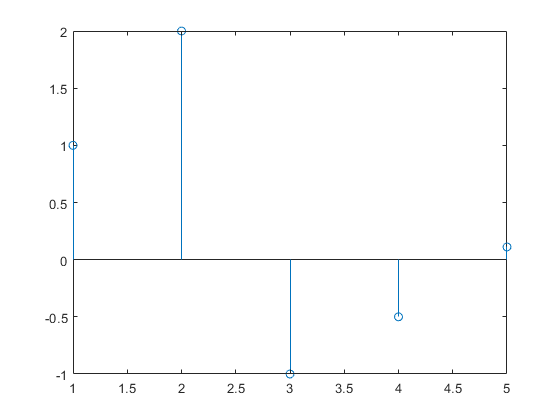

skripta

### 7.2. MATLAB funkcije

Editor možemo koristiti i za pisanje MATLAB funkcija. Pokažimo sada kako izgleda definiranje funkcija i prenošenje varijabli u funkciju te kako funkcija vraća rezultat na primjeru funkcije koja zbraja dva broja. Jedan primjer MATLAB funkcije dan je uz ove materijale i naziva se *zbroji.m.*

Glavna razlika između skripti i funkcija je u tome da MATLAB funkcije započinju s ključnom riječi `function`, dok je sadržaj MATLAB skripte uistinu identičan nizu naredbi koje ručno unosimo u interaktivnom modu rada. Važna razlika između programa i skripti je i doseg varijabli. Sve varijable unutar MATLAB funkcije postoje samo za vrijeme izvođenja funkcije (osim ako se ne radi o globalnoj varijabli), dok sve varijable deklarirane unutar MATLAB skripte postoje i dostupne su unutar interaktivnog korisničkog sučelja. Ime funkcije mora se podudarati s imenom datoteke (bez nastavka .m). Lokalne varijable u funkciji nevidljive su pozivatelju i obrnuto. Prenose se samo ulazni i izlazni argumenti.

Funkcija *zbroji* prima dva ulazna argumenta `a` i `b` te ih zbraja. Unutar MATLAB naredbenog prozora funkciju pozivamo jednostavnim zadavanjem naredbe `zbroji`.

a = 1;
rez = zbroji(a, 2)

rez = 3

### 7.3. Kontrola toka programa

MATLAB razumije osnovne programske petlje (`for`, `while`) te uvjetna i bezuvjetna grananja (`if`, `switch`, `break`) kojima se kontrolira tok programa.

`for` petlja se izvršava na način da brojač unutar petlje poprima sve vrijednosti unutar niza.

n = linspace(1, 4, 4);
for k = n
    disp(k);  % prikaži iznos brojača i
end

     1

     2

     3

     4



Za jednostavno postavljanje početne i konačne vrijednosti može se koristiti i operator ```:"`

a = zeros(1, 3);  % inicijaliziraj vektor a
for k = 1:3
    a(k) = k * k  % na i-to mjesto vektora a ubaci vrijednost i*i
end

a =      1     0     0


a =      1     4     0


a = 1×3
     1     4     9


`while` petlja se izvršava dok je ispunjen logički uvjet petlje:

a = 3;
while (a > 0)
    disp(a)
    a = a - 1; 
end

     3

     2

     1



Naredbu `break` koristimo za bezuvjetni izlazak samo iz `for` ili `while` petlje.

`if` naredba omogućuje uvjetno izvršavanje koda:

a = 10;
b = 5;
if a == b
    rez1 = a - b;
elseif abs(a) == b
    rez1 = a + b;
else 
    rez1 = 0;
end
disp(rez1);

     0



Za kompliciranija uvjetna izvršavanja obično koristimo naredbu `switch`:

a = -1;
switch a
    case -1
        disp('negativna jedinica')
    case 0
        disp('nula')
    case 1
        disp('pozitivna jedinica')
    otherwise
        disp('ostale vrijednosti')
end

negativna jedinica


**Zadatak 9.** Napišite MATLAB skriptu koja na početku generira dva broja `a` i `b`. Zatim napišite funkciju koja kao ulazni argument prima dva broja. Ukoliko su oba ulazna broja pozitivna funkcija vraća zbroj ta dva broja, a ukoliko su oba negativna funkcija vraća razliku prvog i drugog broja. Za ostale slučajeve funkcija vraća $0$. Unutar skripte pozovite napisanu funkciju s `a` i `b` kao ulaznim argumentima te ispišite rezultat pomoću naredbe `disp`.

## 8. Simulink

Simulink je dio MATLAB-a namijenjen simuliranju dinamičkih sustava. Za sam unos i opis sustava koji se simulira koristi se jednostavno grafičko sučelje u kojem sastavljamo/crtamo model kombinirajući gotove komponente. Takvim pristupom je simulacija sustava značajno olakšana jer se od korisnika ne zahtijeva unos diferencijalnih ili diferencijskih jednadžbi koje opisuju sustav uz poznavanje MATLAB programskog jezika već je dovoljno znati blok-shemu sustava.

Simulink se pokreće unutar MATLAB-a zadavanjem naredbe `simulink` ili odabirom ikone iz alatne trake. Nakon pokretanja Simulinka otvara se prozor *Simulink Start Page* prikazan na slici.

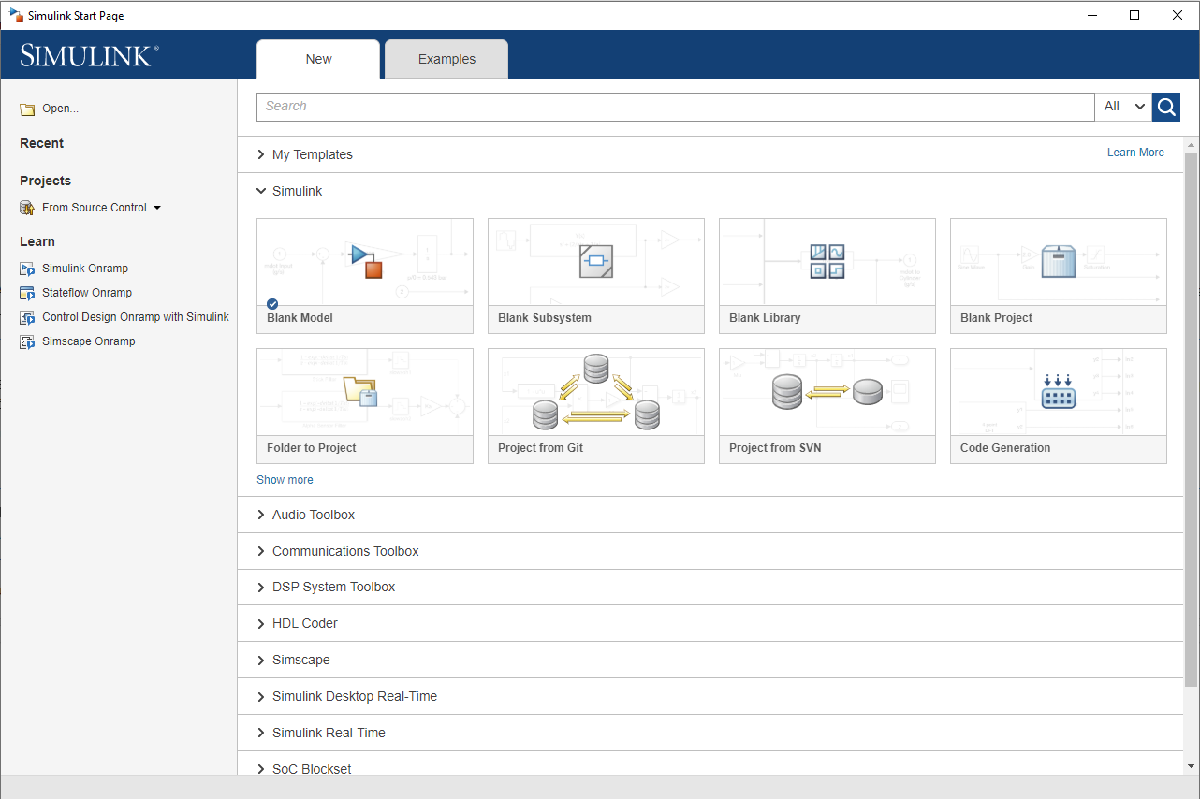

Odabiremo *Blank Model* kako bi kreirali novi model. Zatim se otvara sljedeći prozor prikazan na slici.

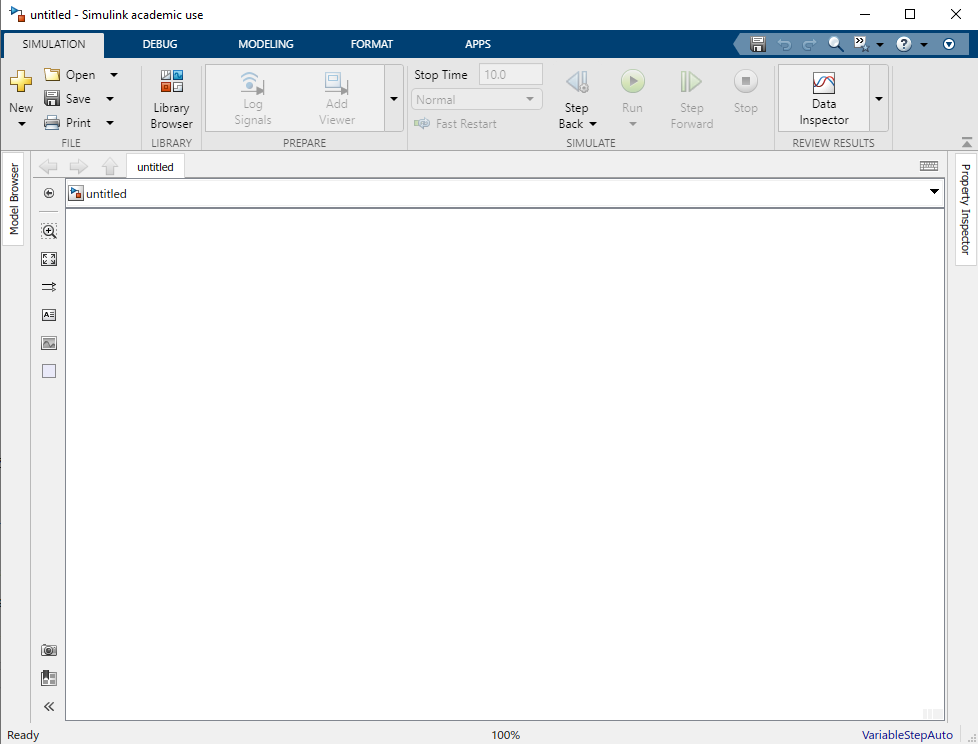

U ovom prozoru sastavljamo model. Kako bi sastavili model, moramo mu dodati elemente odnosno blokove. Kolekcija svih blokova za sastavljanje modela nalazi se u *Simulink Library Browseru. Library browser *otvaramo klikom na ikonu *Library Browser. *Zatim se otvara sljedeći prozor prikazan na slici.

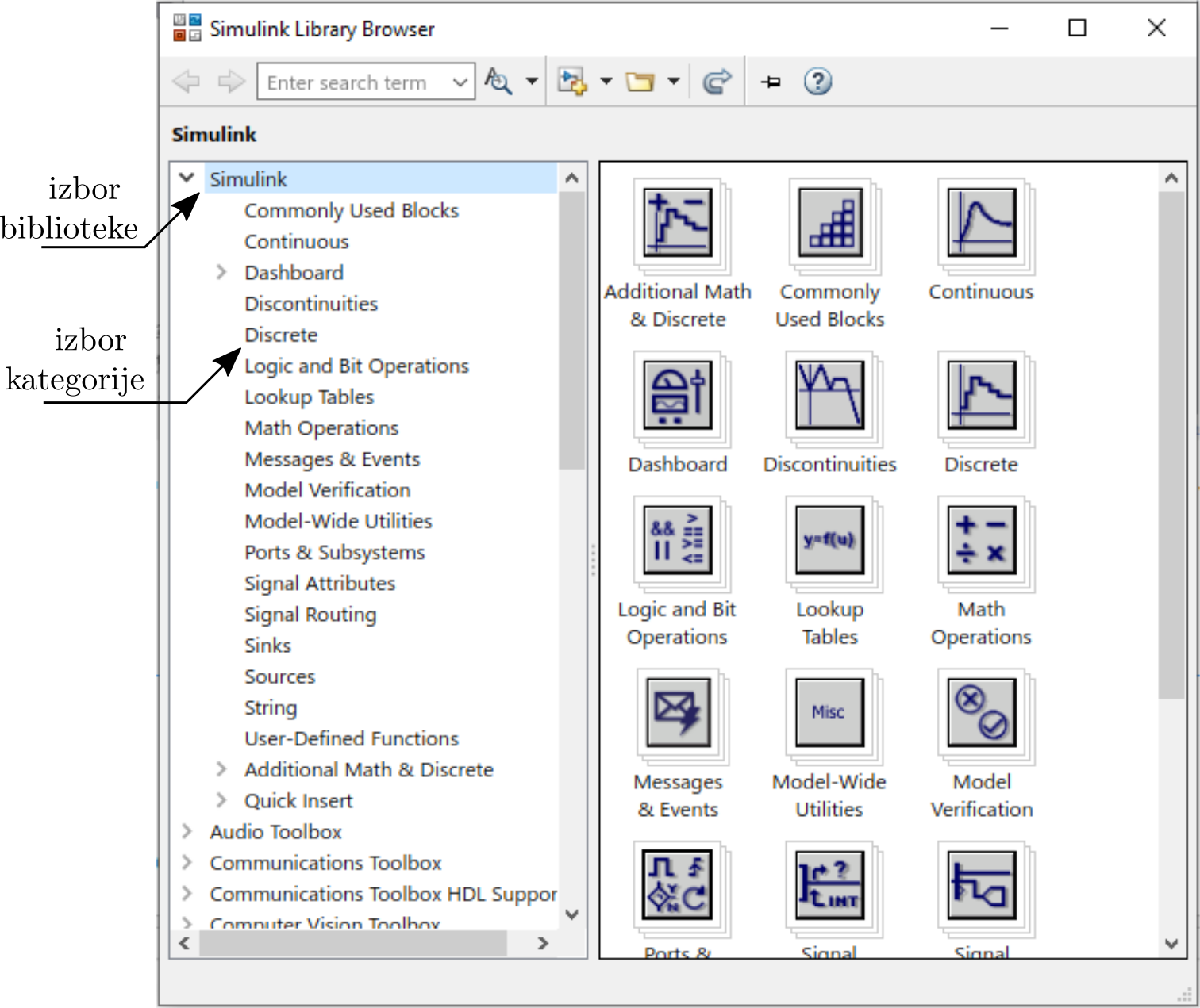

Na model blok dodajemo tako da ga odaberemo u *Simulink Library Browseru*, odvučemo i ispustimo unutar prozora novog modela. Svaki element kojeg smo dodali ima ulazne priključke označene s `>` i izlazne priključke označene s `>`. Blokove spajamo crtanjem veza između blokova (pokazivač se pretvara u alat za crtanje kada ga postavimo iznad ulaznih ili izlaznih priključaka). Dvostrukim klikom na pojedini blok dobivamo izbornik u kojem postavljamo svojstva danog bloka. Primjer jednostavnog modela:

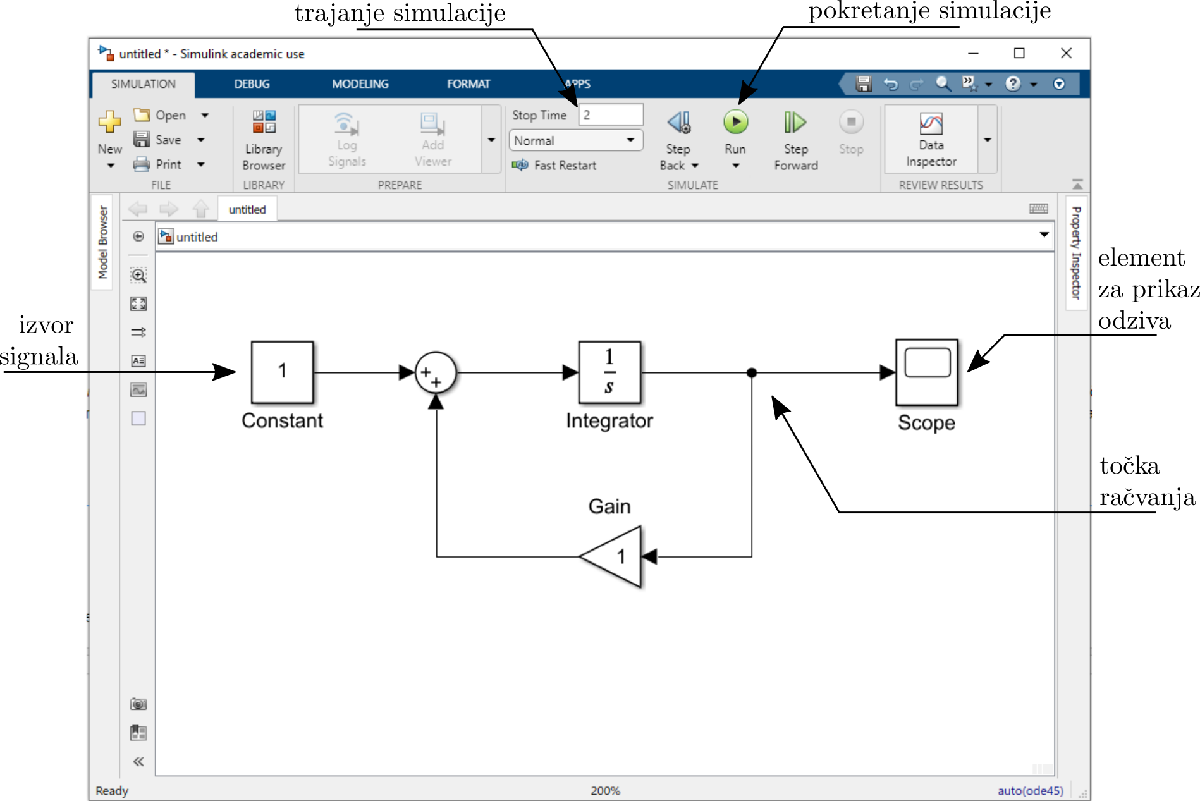

Da bi mogli vidjeti rezultate simulacije nakon pokretanja morate aktivirati *Scope* blok dvostrukim klikom. Sada se otvara prozor prikazan na slici.

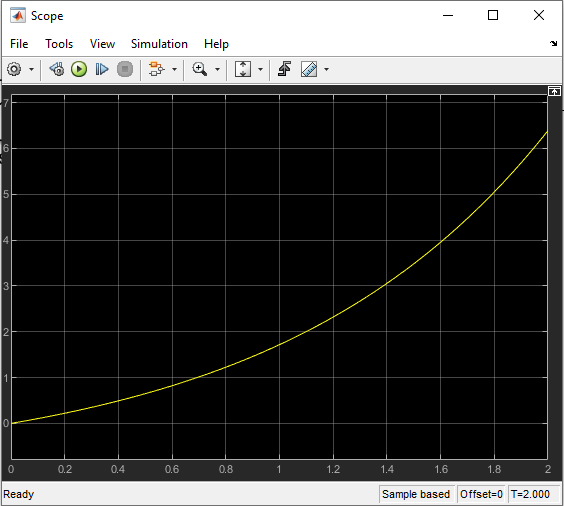

U prozoru vidimo odziv jednostavnog sustava. Simulacijom smo dobili vrijednosti odziva od trenutka $t=0$ do trenutka $t=2$.

Važni parametri simulacije uz početno i konačno vrijeme su vrijednosti vremenskog koraka i tip numeričke integracije koji se koristi. Te i ostale postavke za model se mogu postaviti u izborniku *Modeling -> Model Settings.*

### 8.2. Povezivanje s MATLAB-om

Simulink je sastavni dio MATLAB-a te se pri izgradnji modela mogu koristiti sve MATLAB funkcije. Također se modelu mogu proslijediti neki ulazi, a i rezultati simulacije se mogu dohvatiti iz radnog prostora. Rezultate simulacije možemo spremiti u varijablu koja će biti dostupna u radnom prostoru. Najjednostavniji primjer prikazan je na slici.

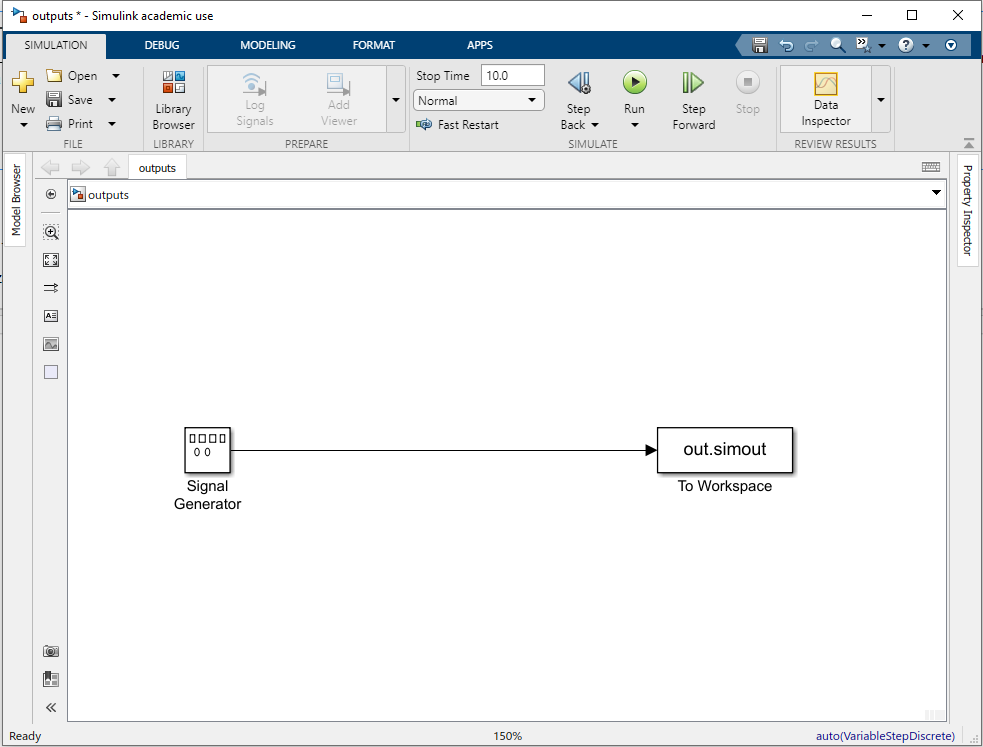

Bitno je staviti postavku *Save format* bloka *To Workspace* na *Array. *To se postiže dvostrukim klikom miša na *To Workspace* i umjesto *Timeseries *odabiremo *Array. *Vrijednosti su spremeljene u strukturi *out* u radnom prostoru. Vrijednostima pristupamo pomoću naredbe *out.simout*, a vremenskim trenutcima s *out.tout. *Sada na tako dobivene rezultate simulacije možemo primijeniti bilo koju od raspoloživih MATLAB funkcija. 

Ponekad je potrebno izvršiti veliki broj simulacija s različitim parametrima. U tom slučaju uobičajen način koji se sastoji od pokretanja simulacije, spremanja rezultata te naposljetku mijenjanja parametara nije pogodan. MATLAB podržava naredbu `sim` koja se može koristiti za pokretanje simulacije. Osim naredbe `sim` mogu se koristiti naredbe `set_param` i `get_param` za mijenjanje parametara modela. Kombiniranjem navedenih naredbi možemo napisati skriptu koja postavlja parametre simulacije i sprema rezultate.

## Korisna literatura

[1] [Get Started with MATLAB](https://www.mathworks.com/help/matlab/getting-started-with-matlab.html), The MathWorks, veljača 2023.

[2] [Get Started with Simulink](https://www.mathworks.com/help/simulink/getting-started-with-simulink.html), The MathWorks, veljača 2023.

[3] T. Petković, Kratke upute za korištenje MATLAB-a, FER, Zagreb, travanj 2005., [https://www.fer.unizg.hr/_download/repository/matlab_upute.pdf](https://www.fer.unizg.hr/_download/repository/matlab_upute.pdf) 